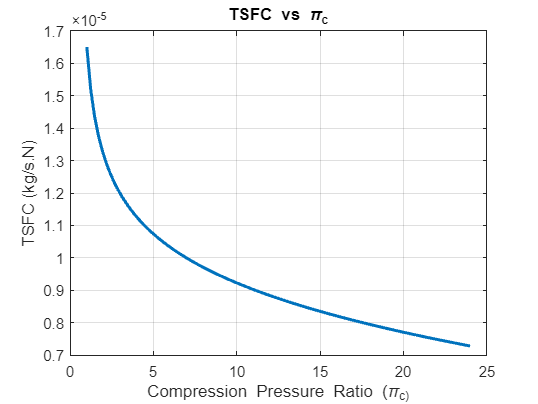

clf
clc
% Problem 6
% Turbo Prop
% To find
% TSFC
% Specific thrust
% Thermal eff
% Propulsive eff
% Overall eff
% Compression pressure ratio - 1 to 24

% Given values
M_a = 0.70;
mdotc = 13.61;
delH = 43960000;
T_o4 = 1389;
C_w_p = 1.0079; % Work coefficient
P_a = 101325;
P_8 = 101325;
T_a = 288.15;
gamma = 1.4;
R = 287;
cp = 1005;
pi_c = linspace(1,24,100);
y = 1;

for i = 1:length(pi_c)
    %Diffuser
    u_a = M_a * sqrt(gamma * R * T_a);
    T_oa = T_a * (1 + ((gamma-1)/2)*M_a^2);
    T_o2 = T_oa;
    P_oa = P_a * (1 + ((gamma-1)/2)*M_a^2)^(gamma/(gamma-1));
    %Compressor
    P_o2 = P_oa;
    P_o3(1,y) = (pi_c(i)) * (P_o2);
    tow_c = (pi_c(i))^((gamma-1)/gamma);
    T_o3(1,y) = tow_c * T_o2;
    %Burner
    mdotf(1,y) = (mdotc * cp * (T_o4 - T_o3(1,y)))/(delH);
    P_o4(1,y) = P_o3(1,y);
    f(1,y) = mdotf(1,y)/mdotc;
    %Turbine
    T_o5(1,y) = T_o4 - (T_o3(1,y) - T_o2); %- (C_w_p * T_a);
    tow_t = T_o5(1,y)/T_o4;
    P_o5(1,y) = P_o4(1,y) * (tow_t)^(gamma/(gamma-1));
    %Nozzle
    P_o8(1,y) = P_o5(1,y);
    P_8 = P_a;
    M_8(1,y) = sqrt((2/(gamma-1))*(((P_o8(1,y)/P_8)^((gamma-1)/(gamma))) - 1));
    T_o8(1,y) = T_o5(1,y);
    T_8(1,y) = T_o8(1,y)/(1 + (((gamma-1)/2)*(M_8(1,y))^2));
    u_8(1,y) = M_8(1,y) * sqrt(gamma * R * T_8(1,y));
    %Propeller
    tow_5 = ((T_oa / T_a) * (tow_c) * (tow_t));
    A = sqrt(((T_o4 / T_a) * (T_a / T_oa) * ((tow_5 - 1) / (tow_c))) / ((T_oa / T_a) - 1)) - 1;
    C_w_j = (gamma - 1) * (M_a)^2 * A;
    C_w_e = C_w_p + C_w_j;
    %Thrust Power
    Thrust_Power(1,y) = C_w_e * mdotc * cp * T_a;
    %Thrust
    F_t(1,y) = Thrust_Power(1,y)/u_a;
    %SFC
    SFC(1,y) = mdotf(1,y)/Thrust_Power(1,y);
    %TSFC
    TSFC(1,y) = mdotf(1,y)/F_t(1,y);
    %Thermal efficiency
    mdot_e = mdotc + mdotf;
    Thermal_eff(1,y) = (((mdot_e/2)*(u_8(1,y))^2) - ((mdotc/2)*(u_a)^2))/(mdotf * delH);
    %Propulsive efficiency
    Propulsive_eff(1,y) = 2/(1 + (u_8(1,y)/u_a));
    %Overall efficiency
    Overall_eff(1,y) = Thermal_eff(1,y)*Propulsive_eff(1,y);
    y = y+1;
end
Thermal_eff;
Propulsive_eff;
Overall_eff;

plot(pi_c,TSFC,'LineWidth',2)
xlabel('Compression Pressure Ratio (\pi_c)')
ylabel('TSFC (kg/s.N)')
title('TSFC vs \pi_c')
grid on

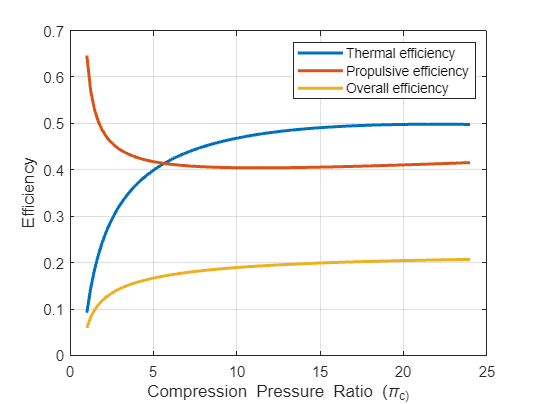


plot(pi_c,Thermal_eff, 'LineWidth',2)
%xlabel('Compression Pressure Ratio (\pi_c)')
hold on
plot(pi_c,Propulsive_eff, 'LineWidth',2)
%xlabel('Compression Pressure Ratio (\pi_c)')
hold on
plot(pi_c,Overall_eff, 'LineWidth',2)
xlabel('Compression Pressure Ratio (\pi_c)')
ylabel('Efficiency')
grid on
legend('Thermal efficiency','Propulsive efficiency','Overall efficiency')